# Set Options for Numeric Data Containing Missing or Incomplete Records

Importing data that has missing or incomplete fields requires recognizing the missing instances and deciding how the missing instances will be imported. Use `importOptions` to capture both these decisions and fetch the data using `readtable`.

Create an import options object for the file, update properties that control the import of missing data, and then use `readtable` to import the data. Note that the dataset `airlinesmall_subset.csv` has two numeric variables `ArrDelay` and `DepDelay`, that contain missing data indicated by `NA`.

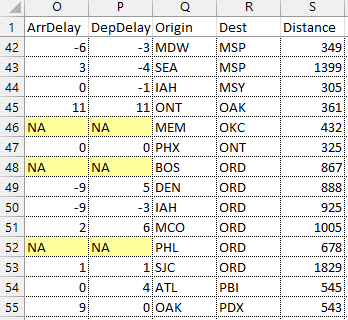

Create an import options object from the file.

opts = detectImportOptions("airlinesmall_subset.csv");

Use the `TreatAsMissing` property to specify the characters in the data that are place holders for missing instances. In this example, the two numeric variables `ArrDelay` and `DepDelay` contain missing fields that contain the text `NA`. 

opts = setvaropts(opts,["ArrDelay","DepDelay"],"TreatAsMissing","NA");

Specify the action for the importing function to take when importing missing instances. See `ImportOptions` properties page for more options.

opts.MissingRule = "fill";

Specify the value to use when the importing function finds a missing instance. Here the missing instances in variables `ArrDelay` and `DepDelay` are replaced by `0`.

opts = setvaropts(opts,["ArrDelay","DepDelay"],"FillValue",0);

Select the variables you want to work with and import them using `readtable`.

opts.SelectedVariableNames = ["ArrDelay","DepDelay"]; 
T = readtable("airlinesmall_subset.csv",opts);

Examine the values in `ArrDelay` and `DepDelay`. Verify that the importing function replaced the missing values denoted by `NA`.

T(42:55,:)

*Copyright 2018 The MathWorks, Inc.*